# Laboratorio 10 Runge Kutta

## Samuel Ramirez Gomez

## Definición función Runge Kutta

function [trayectorias] = Rungekutta(f,A,b,c,h,tin,tfin,init)
var = length(init); %cantdiad de variables a resolver
v = length(c); %Variable v
N = round((tfin-tin)./h,0)% Cantidad de iteraciones
tn = tin; %tiempo inicial
yn = init; %Condiciones iniciales
trayectorias = zeros(N+1,var); %Matriz de trayectorias donde las columnas son cada trayectoria
trayectorias(1,:) = init; %Primera fila son las condiciones iniciales
% Ciclo Runge Kutta
for n = 1:N
    E = zeros(v,var); % Matriz E con v filas y la cantidad de variables como columnas
    K = zeros(v,var); % Matriz K con v filas y la cantidad de variables como columnas
    t = tn + c.*h; % Calculo de T
    E(1,:) = yn; % primera fila E
    K(1,:) = f(t(1),E(1,:)); % primera fila K
    for i = 2:v % ciclo para calculo de las demás posiciones de K y E
        E(i,:) = yn + h.*A(i,1:i-1)*K(1:i-1,:);
        K(i,:) = f(t(i),E(i,:));
    end
yn = yn + (h*b*K); % Calculo de la siguente posición en la trayectoria
trayectorias(n+1,:) = yn; % Insertar las posiciones en la matriz de solucion 
tn = tn +h; % Actualización del tiempo
end
end

## Matrices para Runge Kutta

function [A, b, c] = butcherTable(method)
    switch method
        case 'RK21'  % Heun's Method (2nd order)
            A = [0   0;
                 1   0];
            b = [0.5 0.5];
            c = [0; 1];

        case 'RK22'  % Midpoint Method (2nd order)
            A = [0    0;
                 0.5  0];
            b = [0   1];
            c = [0; 0.5];

        case 'RK31'  % Kutta's 3rd order method
            A = [0    0    0;
                 0.5  0    0;
                -1    2    0];
            b = [1/6, 2/3, 1/6];
            c = [0; 0.5; 1];

        case 'RK32'  % Heun's 3rd order method
            A = [0    0    0;
                 1/3  0    0;
                 0    2/3  0];
            b = [1/4, 0, 3/4];
            c = [0; 1/3; 2/3];

        case 'RK41'  % Classical Runge-Kutta (4th order)
            A = [0    0    0    0;
                 0.5  0    0    0;
                 0    0.5  0    0;
                 0    0    1    0];
            b = [1/6, 1/3, 1/3, 1/6];
            c = [0; 0.5; 0.5; 1];

        case 'RK42'  % 3/8 Rule (alternative RK4)
            A = [0     0     0     0;
                 1/3   0     0     0;
                -1/3   1     0     0;
                 1    -1     1     0];
            b = [1/8, 3/8, 3/8, 1/8];
            c = [0; 1/3; 2/3; 1];

        case 'RK5'  % Butcher's 5th order method (simplified version)
            A = [0     0     0     0     0     0;
                 1/4   0     0     0     0     0;
                 1/8   1/8   0     0     0     0;
                 0     0    1/2    0     0     0;
                 3/16 -3/8  3/8    9/16  0     0;
                -3/7  8/7  -6/7    7/7  2/7   0];
            b = [7/90, 0, 16/45, 2/15, 16/45, 7/90];
            c = [0; 1/4; 1/4; 1/2; 3/4; 1];
            
        otherwise
            error('Método no reconocido. Usa RK21, RK22, RK31, RK32, RK41, RK42 o RK5.');
    end
end

close all
clear

## Circuito 1

sistema de ecuaciones para el circuito 1

%u s (t) = 5 · sin(2π · 50 · t) V, 
% u1 (t = 0) = x1 = 0, 
% u2 (t = 0) = x2 = 0,
% R = 10000 Ohms
% C1 = 0.001 F
% C2 = 0.001 F,
% Is = 10e-8 A,
% Vt = 0.026V

R = 10000;
C1 = 0.001; 
C2 = 0.001;
Is = 10e-8;
Vt = 0.026;
init = [0,0];

Circ1 = @(t,x)([500*pi*cos(2*pi*50*t) + (Is/C1)*(exp(-x(1)/Vt)-1) - (Is/C1)*(exp((x(1)-x(2))/Vt)-1),(Is/C2)*(exp((x(1)-x(2))/Vt)-1)-(1/(R*C2))*x(2)]);
% RK21
[A,b,c] = butcherTable("RK21");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

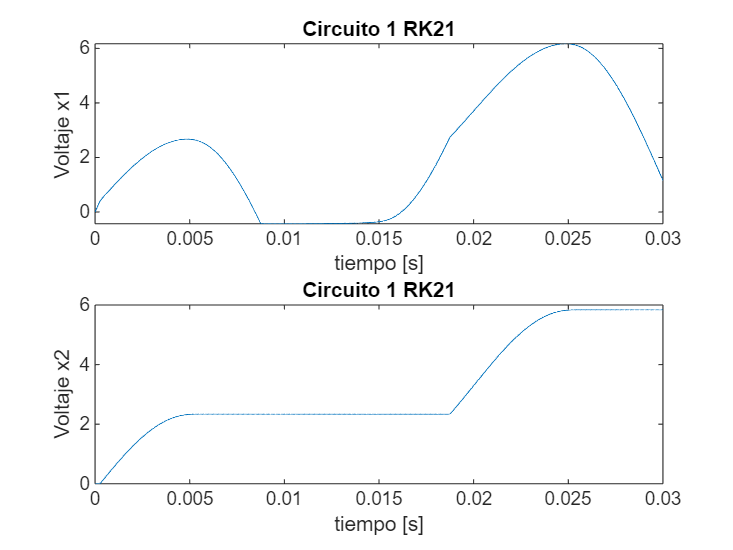

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK21")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK21")
ylabel("Voltaje x2")
xlabel("tiempo [s]")


% RK22
[A,b,c] = butcherTable("RK22");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

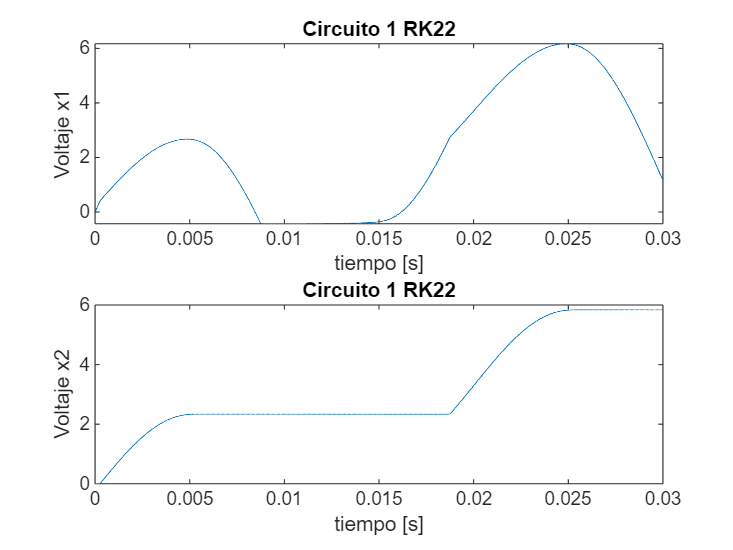

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK22")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK22")
ylabel("Voltaje x2")
xlabel("tiempo [s]")


% RK31
[A,b,c] = butcherTable("RK31");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

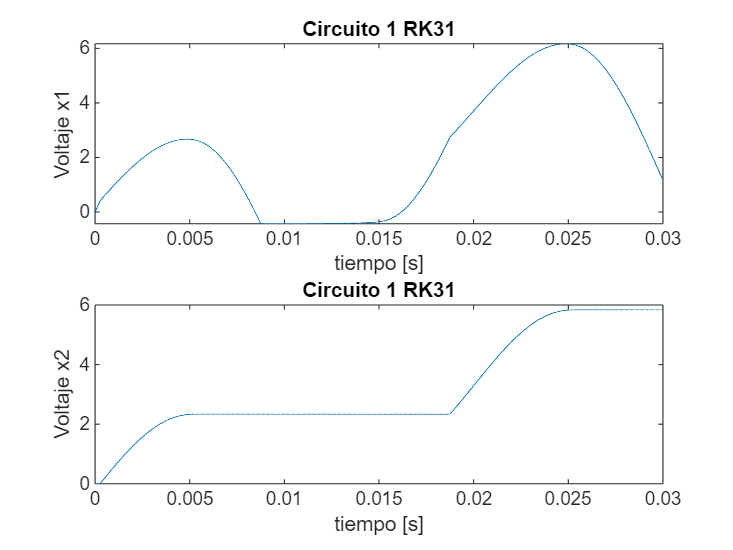

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK31")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK31")
ylabel("Voltaje x2")
xlabel("tiempo [s]")


% RK32
[A,b,c] = butcherTable("RK32");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

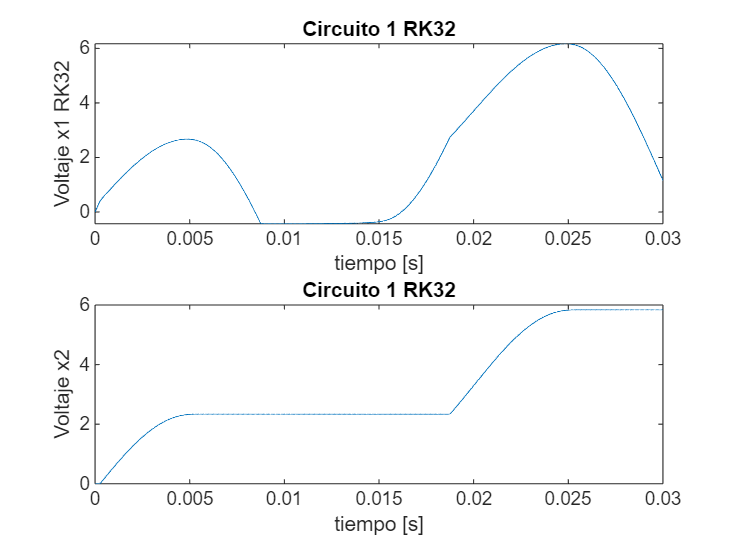

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK32")
ylabel("Voltaje x1 RK32")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK32")
ylabel("Voltaje x2")
xlabel("tiempo [s]")


% RK41
[A,b,c] = butcherTable("RK41");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

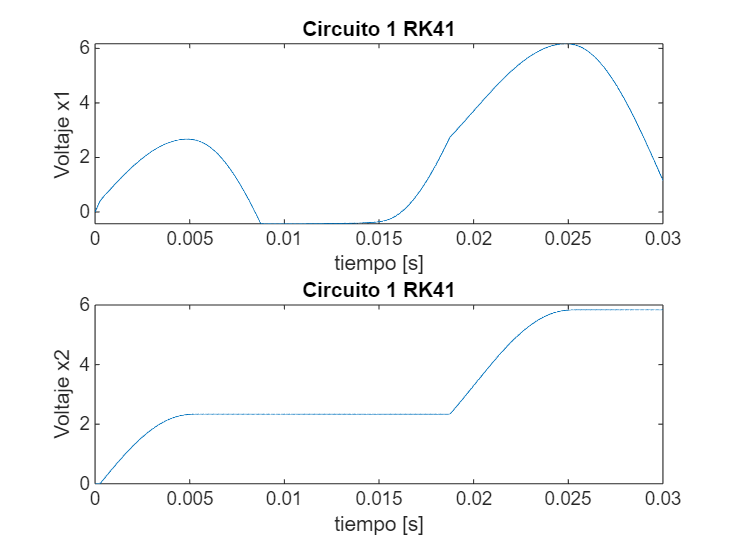

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK41")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK41")
ylabel("Voltaje x2")
xlabel("tiempo [s]")


% RK42
[A,b,c] = butcherTable("RK42");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

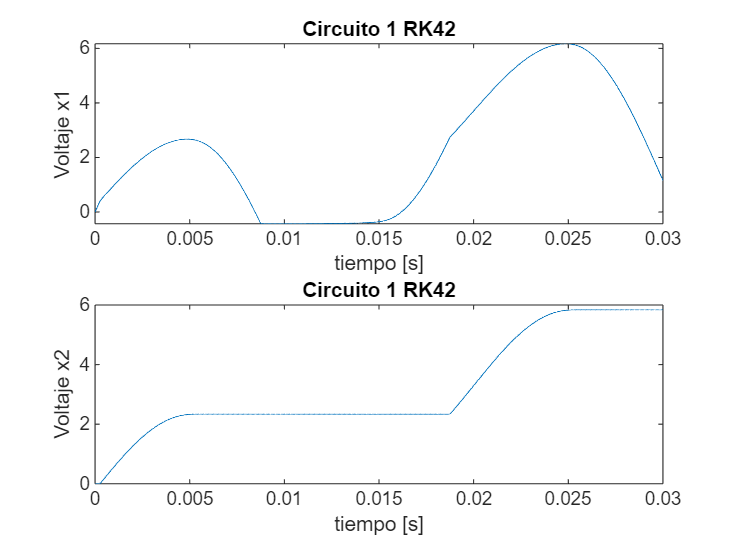

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK42")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK42")
ylabel("Voltaje x2")
xlabel("tiempo [s]")


% RK5
[A,b,c] = butcherTable("RK5");
[sol] = Rungekutta(Circ1,A,b,c,0.000001,0,0.03,init);

N = 30000

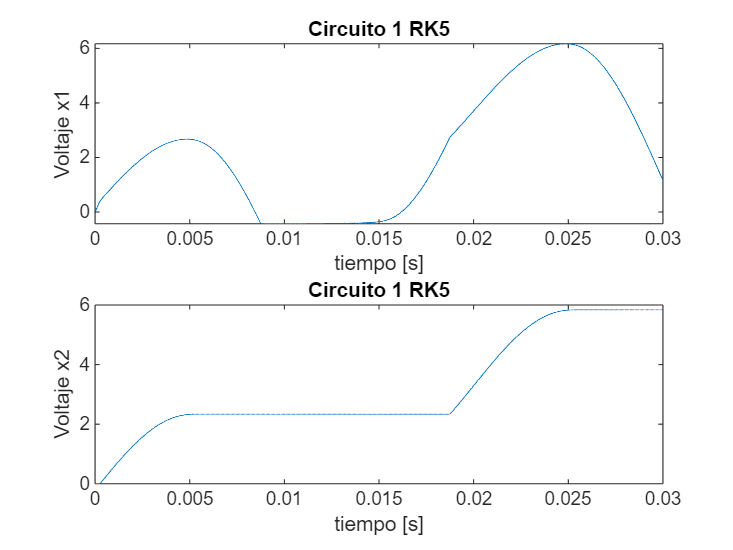

t = 0:0.000001:0.03;
figure
subplot(2,1,1)
plot(t,sol(:,1)')
title("Circuito 1 RK5")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(2,1,2)
plot(t,sol(:,2)')
title("Circuito 1 RK5")
ylabel("Voltaje x2")
xlabel("tiempo [s]")

## Circuito 2

%u1 (t = 0) = 0
%i L (t = 0) = 0
% u2 (t = 0) = 0
% u s (t) = 10 sin(2π · 50 · t) V
%R = 50 Ohm
% C1 = C2 = 1000 μF 
% L = 0.1 H
% delta-t = 0.00001
init = [0,0,0];
us = @(t)(10*sin(2*pi*50*t));
R = 50; % Ohm
C1 = 1000*10e-7; %μF 
C2 = 1000*10e-7; %μF 
L = 0.1; %H
h = 0.00001;
Circ2 = @(t,x)([(1/C1)*x(2) - (1/(C1*R)*x(1)), (1/L)*x(3) - (1/L)*x(1) , (1/C2)*Is*(exp((abs(us(t))-x(3))/(2*Vt))-1)-(1/C2)*x(2)]);

% RK21
[A,b,c] = butcherTable("RK21");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

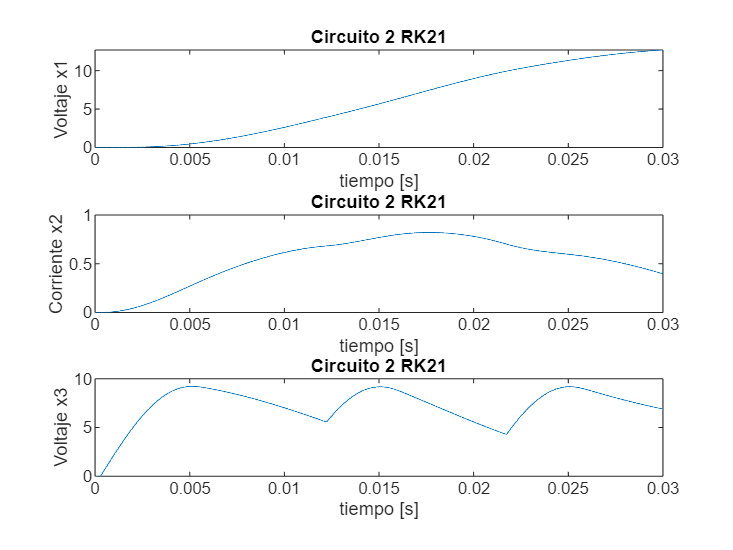

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK21")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK21")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK21")
ylabel("Voltaje x3")
xlabel("tiempo [s]")


% RK22
[A,b,c] = butcherTable("RK22");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

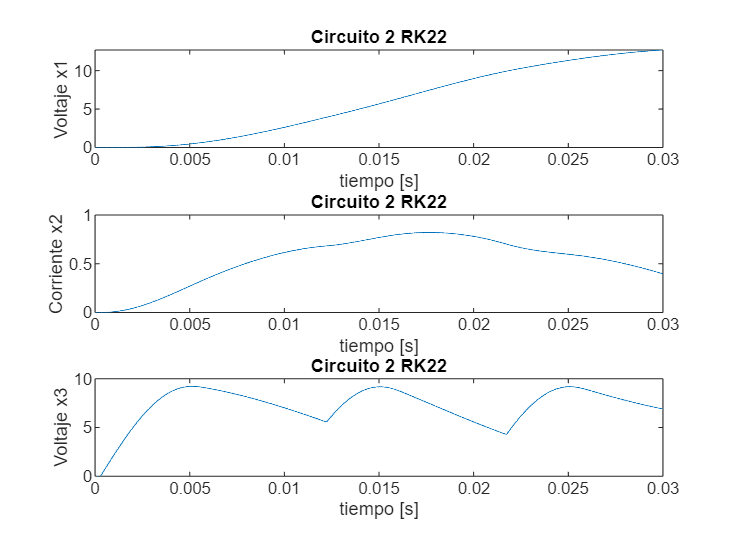

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK22")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK22")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK22")
ylabel("Voltaje x3")
xlabel("tiempo [s]")


% RK31
[A,b,c] = butcherTable("RK31");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

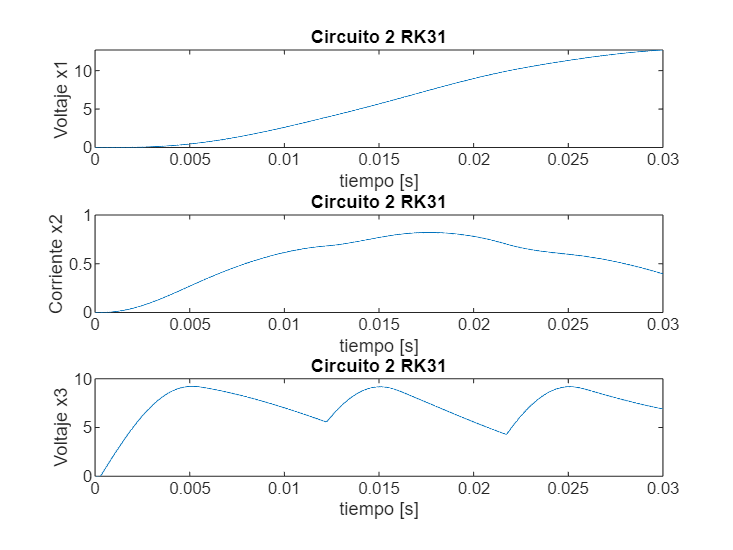

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK31")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK31")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK31")
ylabel("Voltaje x3")
xlabel("tiempo [s]")


% RK32
[A,b,c] = butcherTable("RK32");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

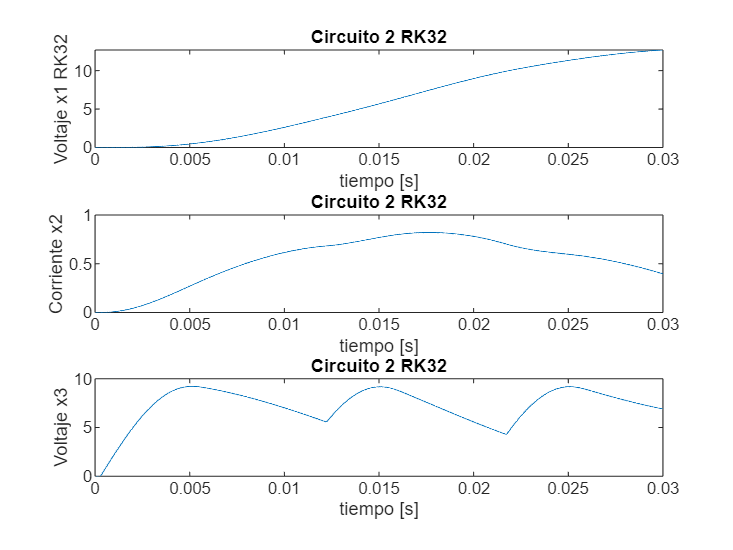

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK32")
ylabel("Voltaje x1 RK32")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK32")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK32")
ylabel("Voltaje x3")
xlabel("tiempo [s]")


% RK41
[A,b,c] = butcherTable("RK41");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

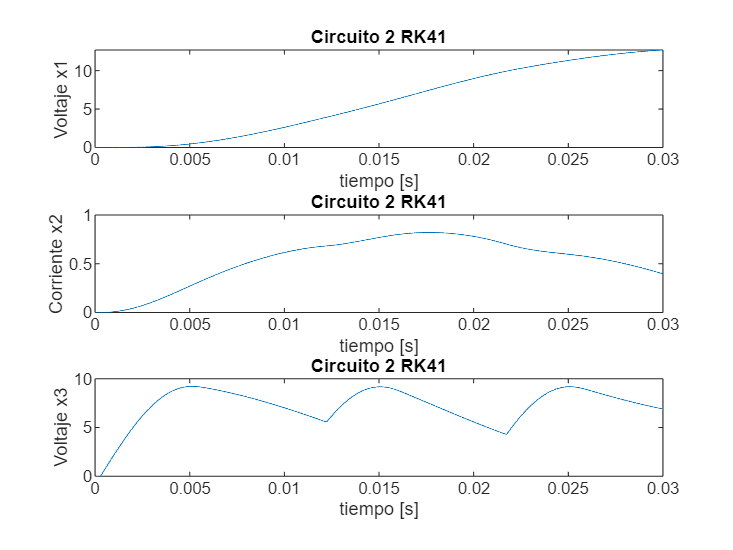

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK41")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK41")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK41")
ylabel("Voltaje x3")
xlabel("tiempo [s]")


% RK42
[A,b,c] = butcherTable("RK42");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

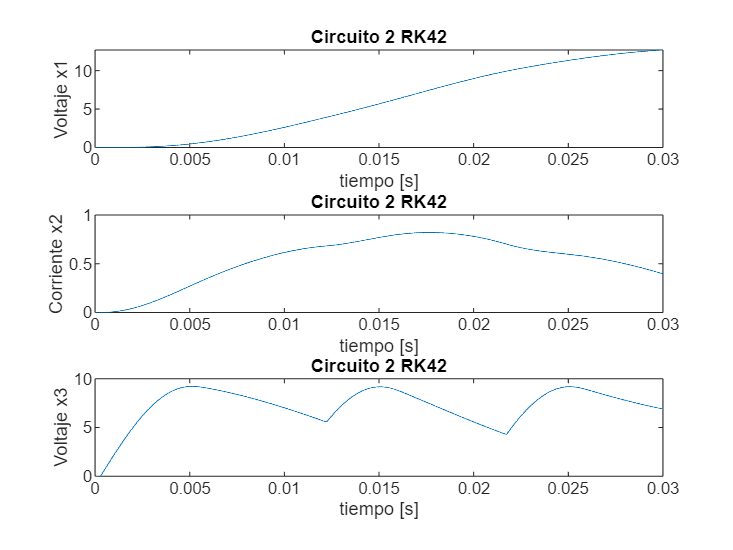

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK42")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK42")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK42")
ylabel("Voltaje x3")
xlabel("tiempo [s]")


% RK5
[A,b,c] = butcherTable("RK5");
[sol] = Rungekutta(Circ2,A,b,c,0.000001,0,0.03,init);

N = 30000

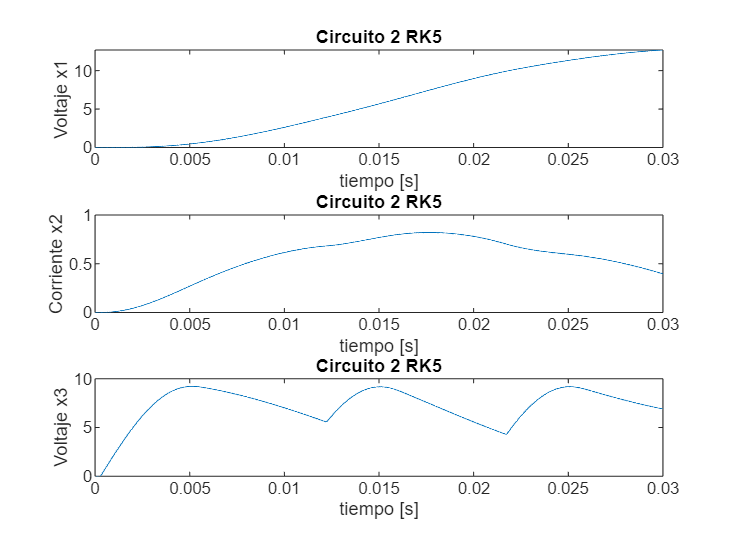

t = 0:0.000001:0.03;
figure
subplot(3,1,1)
plot(t,sol(:,1)')
title("Circuito 2 RK5")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(3,1,2)
plot(t,sol(:,2)')
title("Circuito 2 RK5")
ylabel("Corriente x2")
xlabel("tiempo [s]")
subplot(3,1,3)
plot(t,sol(:,3)')
title("Circuito 2 RK5")
ylabel("Voltaje x3")
xlabel("tiempo [s]")

## Circuito 3

%u1 (t = 0) = p0 = 0
%u2 (t = 0) = q0 = 0
%u3 (t = 0) = v0 = 0
%u4 (t = 0) = z0 = 0 
%C1 = 10 F
%C2 = 100 F 
% R = 50 Ohm
% delta-t = 0.00001 s 
% u s (t) = 5 · sin(2π · 50 · t) 
init = [0,0,0,0];
us = @(t)(5*sin(2*pi*50*t));
dus =  @(t)(500*pi*cos(2*pi*50*t));
R = 50; % Ohm
C1 = 10*10e-6; %μF 
C2 = 100*10e-6; %μF 
C3 = 10*10e-6; %μF 
C4 = 100*10e-6; %μF
h = 0.00001;
safe_exp = @(z) exp(min(z, 400));  % Evita valores mayores a exp(40)

Circ3 = @(t,x)([
    dus(t) + (Is/C1)*(safe_exp(-x(1)/Vt)-1) - (Is/C1)*(safe_exp((x(1)-x(2))/Vt)-1),
    (Is/C2)*(safe_exp((x(1)-x(2))/Vt)-1) - (1/(R*C2))*(x(2)-x(4)),
    dus(t) + (Is/C3)*(safe_exp(x(3)/Vt)-1) + (Is/C3)*(safe_exp((x(4)-x(3))/Vt)-1),
    (1/(R*C4))*(x(2)-x(4)) - (Is/C4)*(safe_exp((x(4)-x(3))/Vt)-1)
]);


% RK21
[A,b,c] = butcherTable("RK21");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

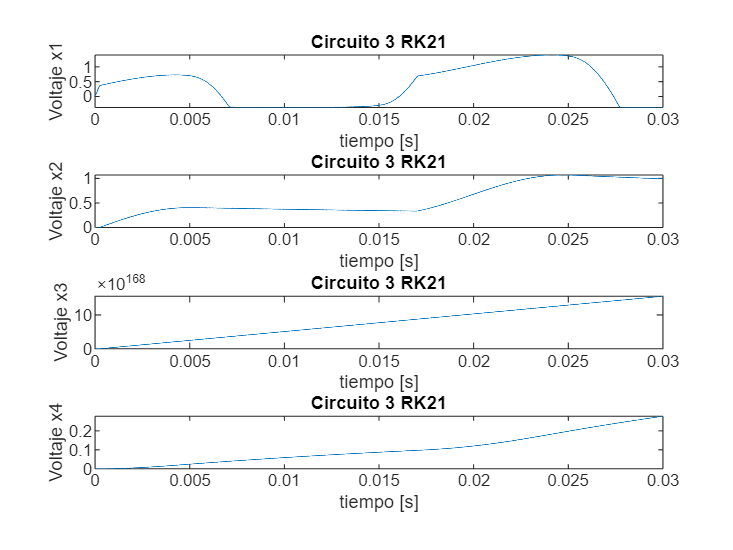

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK21")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK21")
ylabel("Voltaje x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK21")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK21")
ylabel("Voltaje x4")
xlabel("tiempo [s]")


% RK22
[A,b,c] = butcherTable("RK22");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

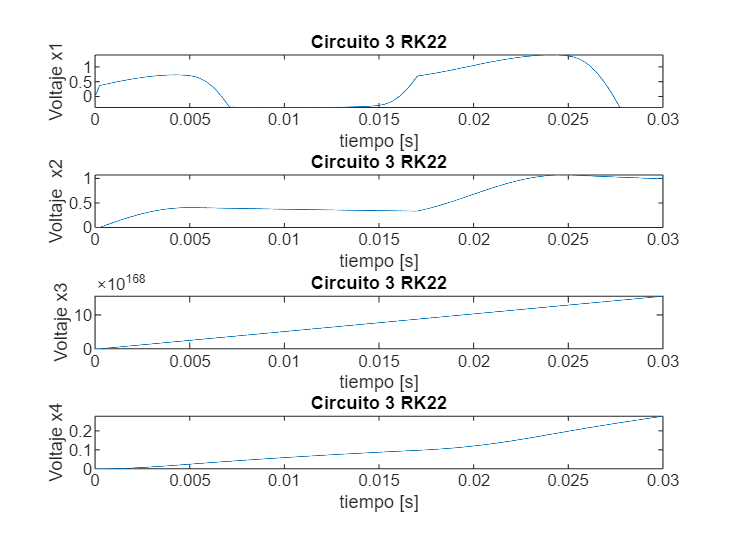

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK22")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK22")
ylabel("Voltaje  x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK22")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK22")
ylabel("Voltaje x4")
xlabel("tiempo [s]")


% RK31
[A,b,c] = butcherTable("RK31");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

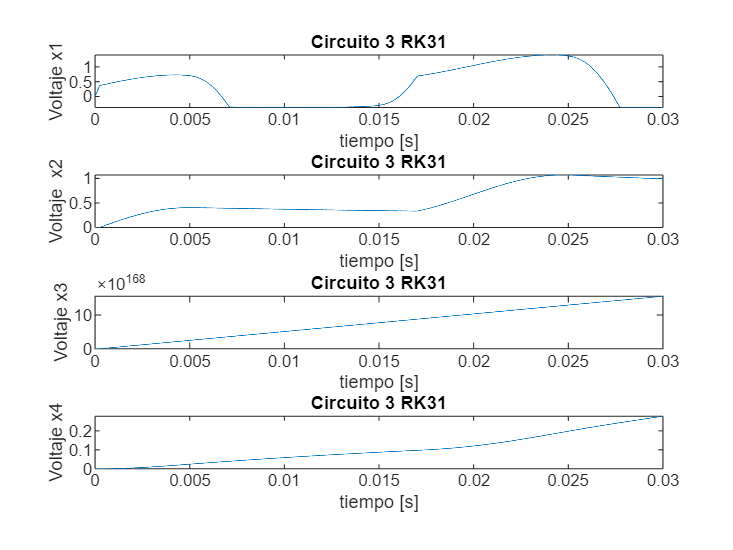

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK31")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK31")
ylabel("Voltaje  x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK31")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK31")
ylabel("Voltaje x4")
xlabel("tiempo [s]")


% RK32
[A,b,c] = butcherTable("RK32");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

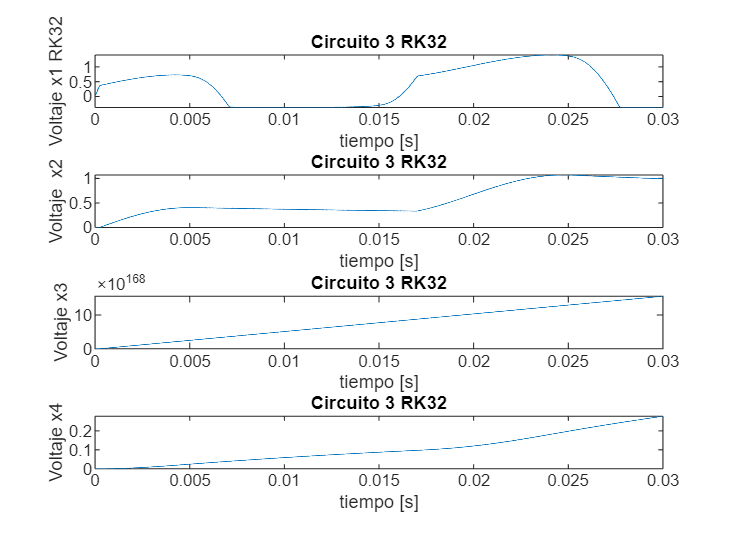

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK32")
ylabel("Voltaje x1 RK32")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK32")
ylabel("Voltaje  x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK32")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK32")
ylabel("Voltaje x4")
xlabel("tiempo [s]")


% RK41
[A,b,c] = butcherTable("RK41");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

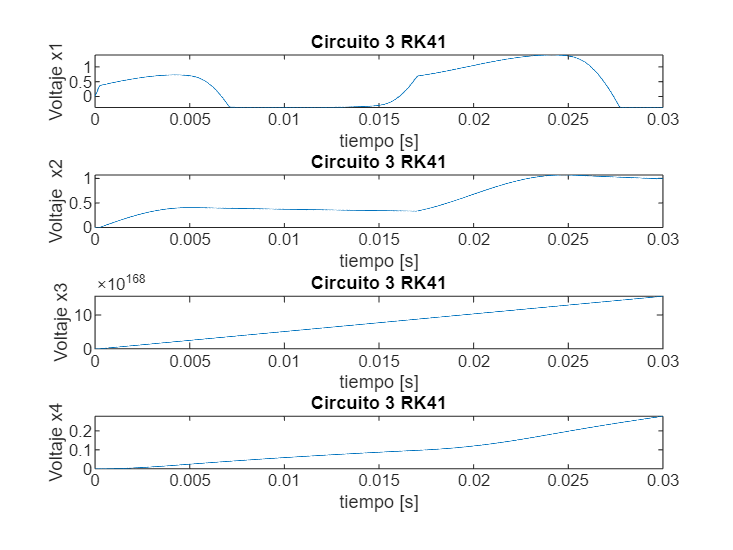

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK41")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK41")
ylabel("Voltaje  x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK41")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK41")
ylabel("Voltaje x4")
xlabel("tiempo [s]")


% RK42
[A,b,c] = butcherTable("RK42");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

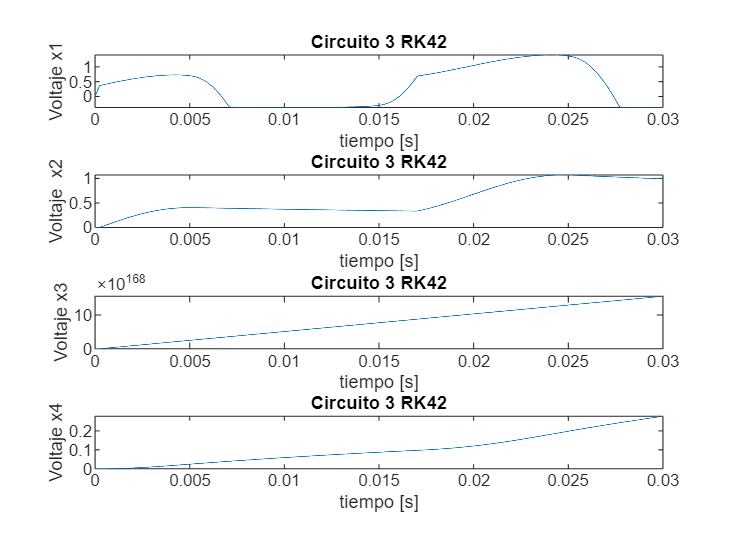

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK42")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK42")
ylabel("Voltaje  x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK42")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK42")
ylabel("Voltaje x4")
xlabel("tiempo [s]")


% RK5
[A,b,c] = butcherTable("RK5");
[sol] = Rungekutta(Circ3,A,b,c,h,0,0.03,init);

N = 3000

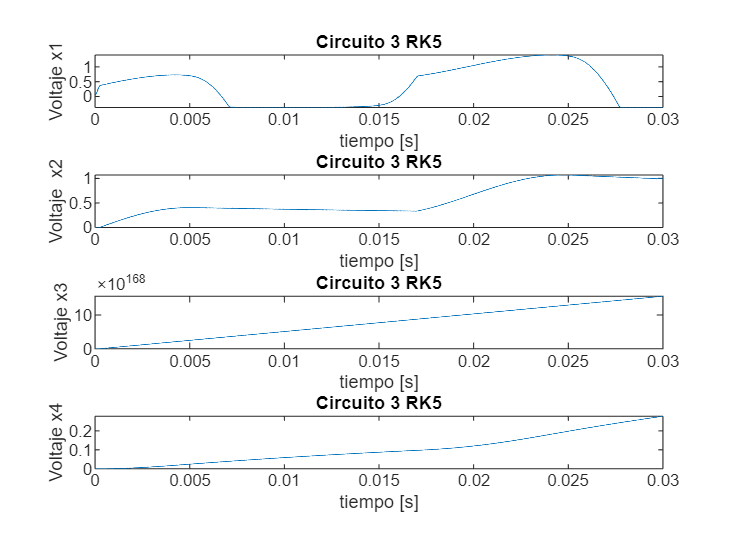

t = 0:h:0.03;
figure
subplot(4,1,1)
plot(t,sol(:,1)')
title("Circuito 3 RK5")
ylabel("Voltaje x1")
xlabel("tiempo [s]")
subplot(4,1,2)
plot(t,sol(:,2)')
title("Circuito 3 RK5")
ylabel("Voltaje  x2")
xlabel("tiempo [s]")
subplot(4,1,3)
plot(t,sol(:,3)')
title("Circuito 3 RK5")
ylabel("Voltaje x3")
xlabel("tiempo [s]")
subplot(4,1,4)
plot(t,sol(:,4)')
title("Circuito 3 RK5")
ylabel("Voltaje x4")
xlabel("tiempo [s]")